# Ejercicio 2.5

 **a) **

tspan = [-10, 0]

tspan =    -10     0


x0 = [1; 0] 

x0 =      1
     0


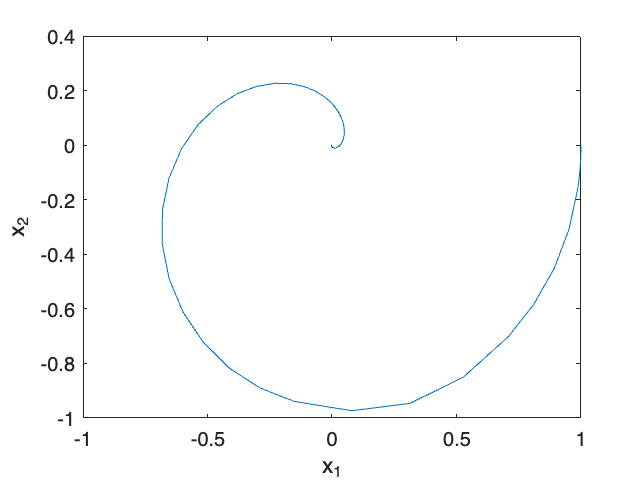

% Solo funciona bien para vectores x0 de módulo menor o igual a 1.
[t, x] = ode45(@(t, x)sistema(t, x), tspan, x0);
%Plot del diagrama de fases
plot(x(:, 1), x(:, 2));
xlabel("x_1")
ylabel("x_2")

**b)**

function xdot = sistema(t, x)
    
    xdot(1,1) = -x(1,1) * (1 - x(1,1)^2 - x(2,1)^2) + x(2,1);
    xdot(2,1) = -x(2,1) * (1 - x(1,1)^2 - x(2,1)^2) - x(1,1);

end